Read in model https://www.mathworks.com/matlabcentral/answers/458426-how-to-run-the-model-in-sbml-file

modelObj = sbmlimport('test.xml');

blah blah

% https://www.mathworks.com/matlabcentral/answers/184627-integration-tolerance-not-met-in-simbiology
% https://www.mathworks.com/help/simbio/ref/solveroptions.html
cs = getconfigset(modelObj);
cs.SolverType

ans = 'ode15s'

cs.MaximumNumberOfLogs

ans = Inf

cs.SolverOptions.AbsoluteTolerance

ans = 1.0000e-06

cs.SolverOptions.AbsoluteToleranceScaling

ans = logical
   1


cs.SolverOptions.RelativeTolerance

ans = 1.0000e-03

cs.SolverOptions.AbsoluteToleranceStepSize


ans =

  0×1 empty double column vector




cs.MaximumNumberOfLogs = 100

cs =    Configuration Settings - default (active)
     SolverType:                   ode15s
     StopTime:                     10

   SolverOptions:
     AbsoluteTolerance:            1e-06
     AbsoluteToleranceScaling:     true
     RelativeTolerance:            0.001
     SensitivityAnalysis:          false

   RuntimeOptions:
     StatesToLog:                  all

   CompileOptions:
     UnitConversion:               false
     DimensionalAnalysis:          false

   SensitivityAnalysisOptions:
     Inputs:                       0
     Outputs:                      0


cs.SolverOptions.AbsoluteToleranceScaling = false

cs =    Configuration Settings - default (active)
     SolverType:                   ode15s
     StopTime:                     10

   SolverOptions:
     AbsoluteTolerance:            1e-06
     AbsoluteToleranceScaling:     false
     RelativeTolerance:            0.001
     SensitivityAnalysis:          false

   RuntimeOptions:
     StatesToLog:                  all

   CompileOptions:
     UnitConversion:               false
     DimensionalAnalysis:          false

   SensitivityAnalysisOptions:
     Inputs:                       0
     Outputs:                      0


%cs.SolverOptions.AbsoluteTolerance = 1e-6

Test simulation

%[isUpdated, changes, modelBackup] = updateDuplicateNames(modelObj)
[t, x, names] = sbiosimulate(modelObj)

t = 1.0e-04 *

         0
    0.0010
    0.0011
    0.0012
    0.0013
    0.0013
    0.0014
    0.0014
    0.0015
    0.0015


x = 1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0000    0.0000   -0.0001         0    0.0000   -0.0001    0.0001         0         0    0.0001    0.0000         0         0         0         0         0    0.0000         0         0   -0.0000    0.0000    0.0000         0    0.0000         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000   -0.0000    0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0    0.0000    0.0000    0.0000   -0.0000         0    0.0000         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    

names = 62×1 cell array
    {'H_e'     }
    {'W_x'     }
    {'W_i'     }
    {'H_i'     }
    {'K_i'     }
    {'dG_H'    }
    {'J_DH'    }
    {'J_C1'    }
    {'dG_C1op' }
    {'J_C3'    }
    {'dG_C3op' }
    {'J_C4'    }
    {'dG_C4op' }
    {'J_F1'    }
    {'J_ANT'   }
    {'Psi_x'   }
    {'Psi_i'   }
    {'J_MgATPx'}
    {'ATP_fx'  }
    {'J_MgADPx'}
    {'ADP_fx'  }
    {'J_MgATPi'}
    {'ATP_fi'  }
    {'J_MgADPi'}
    {'ADP_fi'  }
    {'J_ATP'   }
    {'J_ADP'   }
    {'J_AMP'   }
    {'J_Pi2'   }
    {'J_Pi1'   }


Plot test results

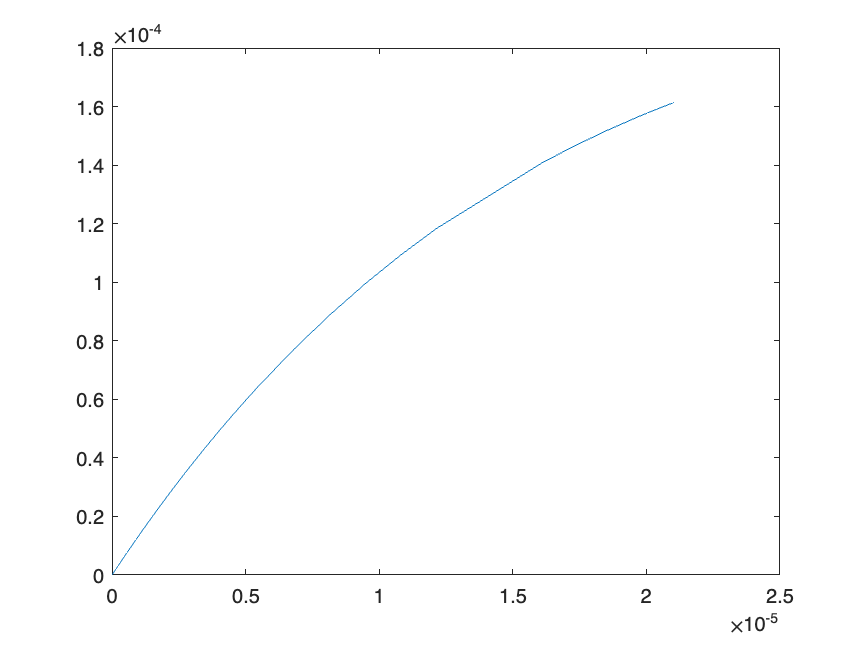

% ATP final concentration
plot(t,x(:,23))

Get model parameters

% get values of original parameters and save for manipulating
params = sbioselect(modelObj, 'Type', 'parameter')

params =    SimBiology Parameter Array

   Index:    Name:       Value:         Units:
   1         t           1                    
   2         Mg_tot      0.005                
   3         Pi_e        0.001                
   4         ADP_e       0.0013               
   5         RT          2.4734               
   6         F           0.096485             
   7         n_A         3                    
   8         dG_C1o      -69.37               
   9         dG_C3o      -32.53               
   10        dG_C4o      -122.94              
   11        dG_F1o      36.03                
   12        pH_e        7.1                  
   13        H_e         1                    
   14        K_e         0.15                 
   15        ATP_e       0                    
   16        AMP_e       0                    
   17        k_dHPi      1.77828e-07          
   18        k_dHatp     3.31131e-07          
   19        k_dHadp     5.12861e-07          
   20        K_DT   


% x_C1 = complex I, paramter 39
c1_orig = params(39).Value

c1_orig = 0.3692

% x_C3 = complex III, paramter 40
c3_orig = params(40).Value

c3_orig = 0.0917

% x_C4 = complex IV, paramter 41
c4_orig = params(41).Value

c4_orig = 3.2562e-05

% find C5 and add in
% ATP_fi parameter 23 starts at 0
% O2 is parameter 113




test altering parameter

%params2 = sbioselect(modelObj, 'Type', 'parameter')
%params2(39)
warning('off','all')

%[t2, x2, names2] = sbiosimulate(modelObj);

% ATP_fi parameter 23 starts at 0, column 23 as well in results
% O2 is parameter 113 in the model, column 62 in results

adjustments = 0:0.05:0.5

adjustments =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000



c1 = array2table(zeros(0,3))


c1 =

  0×3 empty table



c1.Properties.VariableNames = ["time", "ATP", "O2"];
complex = "ComplexI";
%for l=1:length(adjustments);
for l=1:3
    params(39).Value = c1_orig * adjustments(l);
    [t2, x2, names2] = sbiosimulate(modelObj);
    c1temp = table(t2, x2(:,23), x2(:,62));
    c1temp.Properties.VariableNames = ["time", "ATP", "O2"];
    c1 = [c1; c1temp];
end

test rerun

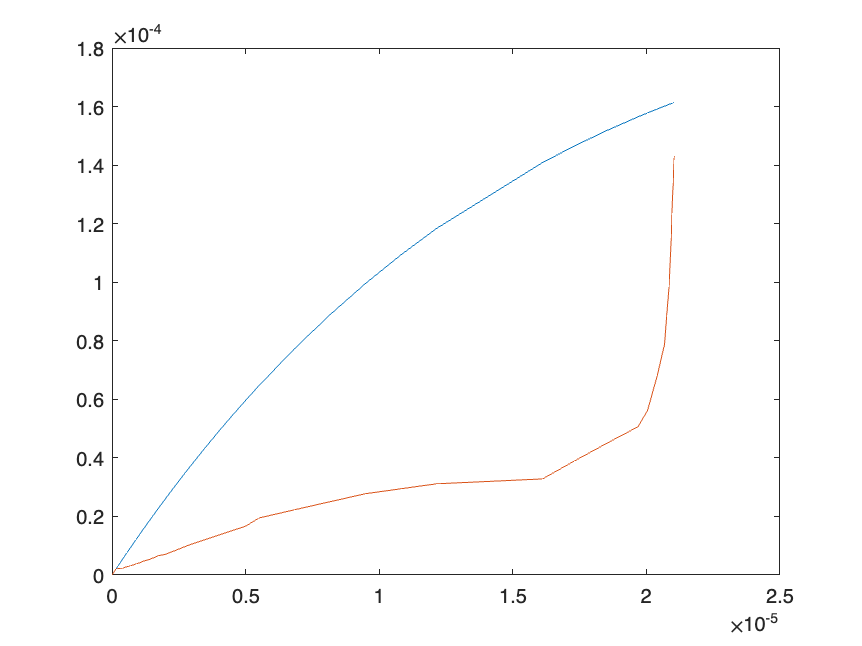

% ATP final concentration
plot(t,[x(:,23), x2(:,23)])

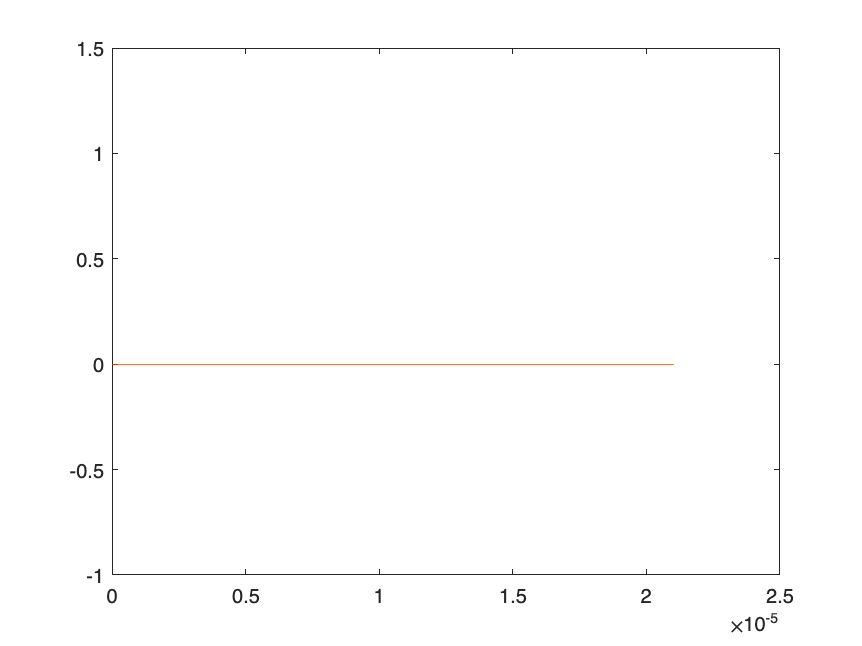


plot(t,[x(:,62), x2(:,62)])


% do a range of altering complex I compare to range of complex III, complex
% V